# Aerodynamic Drag Experiment Master Code

## Parameter Declaration

clear all;

Define variables

global alpha;
global m;
global g;
global tstep;
global tend;
global wind;

Set known values (ft, slugs, sec) Several of these can be found in the lab document introduction These are the physical parameters of the test conditions, which only need to be changed for different projectiles and different test conditions

Xo=0;                           % Initial Horizontal Position (ft)
dia= 2.76;                     % Projectile Diameter (in)

rho= 2.38e-3;                    % Air Density (slugs/ft^3)
g= 32.2;                         % Acceleration Due to Gravity (ft/s^2)
m= 1.98e-3;                   % Projectile Mass (slugs)
C= 0.47;                         % (change) Drag Coefficient
tend=10;                         % Maximum time solved for. Increase this for more values (s)
tstep=0.001;                    % Time Step (s)
nu=(1.516*10^-5)*(3.281*3.281); % Kinematic Viscosity (ft^2/s)

% These are the experimental values you will measure in each test
Yo= 0;             %(change) Initial Vertical Position (ft)
Vx = 0.1;                  %(change) Initial Velocity (ft/s)
Vy = -0.5;            % (change) Initial Velocity y (ft/s)            
Vo = sqrt(Vx^2 + Vy^2);    %Initial Velocity (ft/s)
T= atan2(Vy,Vx) * 180 /pi;   %Initial Angle (degrees from horizontal)
wind=0;

A=pi*(dia/(2*12))^2;            % Cross-Sectional Area
alpha=.5*rho*C*A;
Re=Vo*(dia/12)/nu;              % Reynolds number calculation
ang=pi*T/180;

## Projectile Motion

t=0:tstep:tend;[t,X,Y,Vx,Vy]=Motioncalc(Xo,Yo,Vo,ang,C);

Finding Horizontal Travel Distance

for count=1:1:length(Y)
    if Y(count)<0
        break;
    end
end
disp('Theoretical Zero-Drag Landing Time (s):');((Vo*sin(ang)+sqrt((Vo*sin(ang))^2+2*g*Yo))/g)

Theoretical Zero-Drag Landing Time (s):


ans = 0

Pre-lab Question 1

disp('Theoretical Zero-Drag Landing Point (ft):');Xo+Vo*cos(ang)*((Vo*sin(ang)+sqrt((Vo*sin(ang))^2+2*g*Yo))/g)

Theoretical Zero-Drag Landing Point (ft):


ans = 0

Question 7

disp('Simulated 2D Drag Landing Time (s):');t(count-1)

Simulated 2D Drag Landing Time (s):


ans = 0

disp('Simulated 2D Drag Landing Point (ft):');X(count-1)

Simulated 2D Drag Landing Point (ft):


ans = 0

Distance vs. height plot

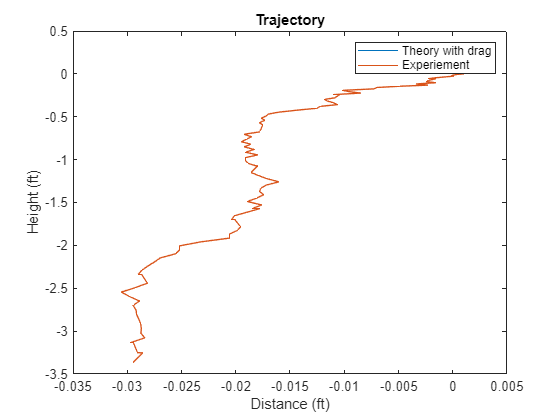

Exp_Data_File  % (change) execute the file contains the experiemental data = [t, x, y]
plot(X(1:count-1),Y(1:count-1) ,'DisplayName' ,'Theory'); % plot theoretical projectile with drag
hold on
plot( (data(:,2)), (data(:,3)+Yo) ); % plot the experiemenal projectile
legend('Theory with drag', 'Experiement')
title('Trajectory'); %Graph title
xlabel('Distance (ft)'); %x-axis label
ylabel('Height (ft)'); %y-axis label
hold off

% calculate mean squared error
xv = linspace(max(X(1),data(1,2)), min(X(end),data(end,2)),200);
ytheo = interp1(X,Y,xv,'pchip');
yexp = interp1(data(:,2), data(:,3)+Yo,xv,'pchip');
disp('The MSE error between theory and experiment is:');mean((ytheo-yexp).^2)

The MSE error between theory and experiment is:


ans = 15.7734

## Terminal Velocity

Vt=sqrt(m*g/alpha);

[t,Xt,Yt,Vxt,Vyt]=Motioncalc(Xo,Yo,0,-pi/2,C);
% Terminal Velocity Calculation
for i=1:length(Vyt)
    if -Vyt(i)>=Vt*0.99
        break
    end
end

Velocity Plot

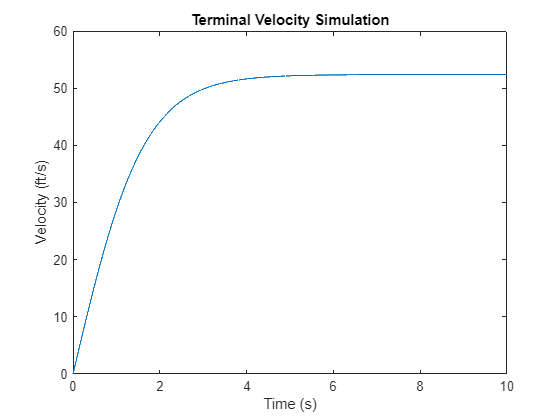

plot(t,-Vyt(:));
xlabel('Time (s)'); % x-axis label
ylabel('Velocity (ft/s)'); % y-axis label
title('Terminal Velocity Simulation')

Question 1

disp('Analytical Terminal Velocity (ft/s):');Vt

Analytical Terminal Velocity (ft/s):


Vt = 52.3800

Question 2

disp('Approx. Simulated Terminal Velocity (ft/s):');-Vyt(i)

Approx. Simulated Terminal Velocity (ft/s):


ans = 51.8566

disp('Time to 99% of Terminal Velocity (s):');t(i)

Time to 99% of Terminal Velocity (s):


ans = 4.3040

Question 3

disp('Minimum Drop Height for Terminal Velocity (ft):'); -Yt(i)+Yo

Minimum Drop Height for Terminal Velocity (ft):


ans = 166.8251

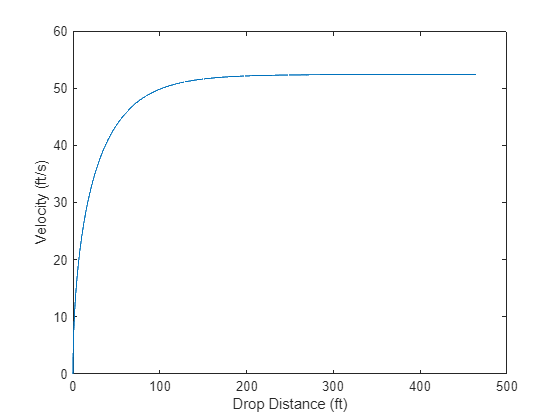

plot(-Yt,-Vyt);xlabel('Drop Distance (ft)'); % x-axis label
ylabel('Velocity (ft/s)'); % y-axis label

## Baseball Trajectory

New Physical Parameters

 Yo=4;       %Initial Vertical Position (ft)
 dia=9.125/pi;      %Projectile Diameter (in)
 T=40;          %Initial Angle (degrees from horizontal)
 m=5.125/514.785;       %Projectile Mass (slugs)
 ang=pi*T/180;
 tend=20;
% 
 A=pi*(dia/(2*12))^2;
 alpha=.5*rho*C*A;

Question 10

 disp('Initial Velocity Without Wind (ft/s):');wind=0;Baseball(Xo,Yo,ang,C)

Initial Velocity Without Wind (ft/s):


ans = 170

Question 11

 disp('Initial Velocity With -10 Wind (ft/s):');wind=10;Baseball(Xo,Yo,ang,C)

Initial Velocity With -10 Wind (ft/s):


ans = 195

Question 12

 disp('Initial Velocity With +10 Wind (ft/s):');wind=-10;Baseball(Xo,Yo,ang,C)

Initial Velocity With +10 Wind (ft/s):


ans = 153

function Vo=Baseball(Xo,Yo,ang,C)
THERE=1;
    for Vo=150:1:250
        [t,X,Y,Vx,Vy]=Motioncalc(Xo,Yo,Vo,ang,C);
        for count=1:length(Y)
            if Y(count)>37
                THERE=count;
            end

        end
        if X(THERE)>344 && X(THERE)<346
            break
        end
        
    end
    %THERE
    %X(THERE)
end

function [t,X,Y,Vx,Vy]=Motioncalc(Xo,Yo,Vo,ang,C)

    %Define variables
    global alpha;
    global m;
    global g;
    global tstep;
    global tend;
    global wind;
    t=0:tstep:tend;
    
    Vox=Vo*cos(ang);
    Voy=Vo*sin(ang);
    wind2=wind*1.467; % mph to ft/s conversion
    
    X=zeros(length(t),1);Y=zeros(length(t),1);
    Vx=zeros(length(t),1);Vy=zeros(length(t),1);
    Ax=zeros(length(t),1);Ay=zeros(length(t),1);
    X(1)=Xo;Y(1)=Yo;Vx(1)=Vox;Vy(1)=Voy;
    
    % Equations of motion with initial conditions
    Ax(1)=-alpha/m*((Vox+wind2)^2+Voy^2)^0.5*(Vox+wind2);
    Ay(1)=-g-alpha/m*((Vox+wind2)^2+Voy^2)^0.5*Voy;
    
    
    % Loop to numerically solve non-linear differential equation using a
    % variation of the central difference approximation method
    for i=1:length(t)-1
        % Update velocities using forward differences
        Vx(i+1)=Vx(i)+Ax(i)*(t(i+1)-t(i));
        Vy(i+1)=Vy(i)+Ay(i)*(t(i+1)-t(i));
        
        % Update positions using the average of the speeds between previous
        % and new values (for better accuracy)
        X(i+1)=X(i)+1/2*(Vx(i)+Vx(i+1))*(t(i+1)-t(i));
        Y(i+1)=Y(i)+1/2*(Vy(i)+Vy(i+1))*(t(i+1)-t(i));
            
        % Update accelerations (equation 1 in the lab handout) for the next
        % step using the new speed values
        Ax(i+1)=-alpha/m*((Vx(i+1)+wind2)^2+Vy(i+1)^2)^0.5*(Vx(i+1)+wind2);
        Ay(i+1)=-g-alpha/m*((Vx(i+1)+wind2)^2+Vy(i+1)^2)^0.5*Vy(i+1);
    end
end